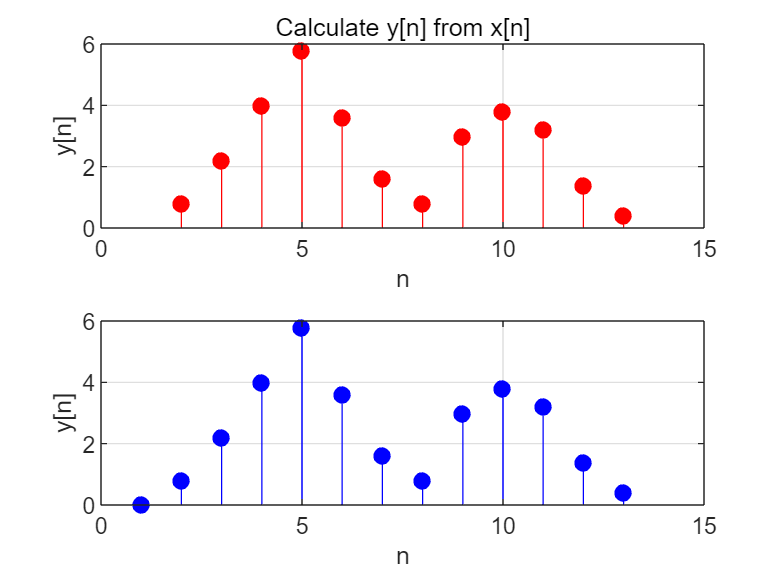

clc,clear,close all;
nx=1:10;
x=[1 2 3 4 0 0 1 3 2 1];
nh=1:3;
h=0.8*(nh==1)+0.6*(nh==2)+0.4*(nh==3);
y=conv(x,h);
ny=nx(1)+nh(1):nx(end)+nh(end);
figure;
subplot(2,1,1),stem(ny,y,'r','filled'),xlabel('n'),ylabel('y[n]'),grid on,xlim([0 15]);
title('Calculate y[n] from x[n]');
a=[1];
b=[0 0.8 0.6 0.4];
nx=1:13;
x=[1 2 3 4 0 0 1 3 2 1 0 0 0];
y=filter(b,a,x);
subplot(2,1,2),stem(nx,y,'b','filled'),xlabel('n'),ylabel('y[n]'),grid on,xlim([0 15]);

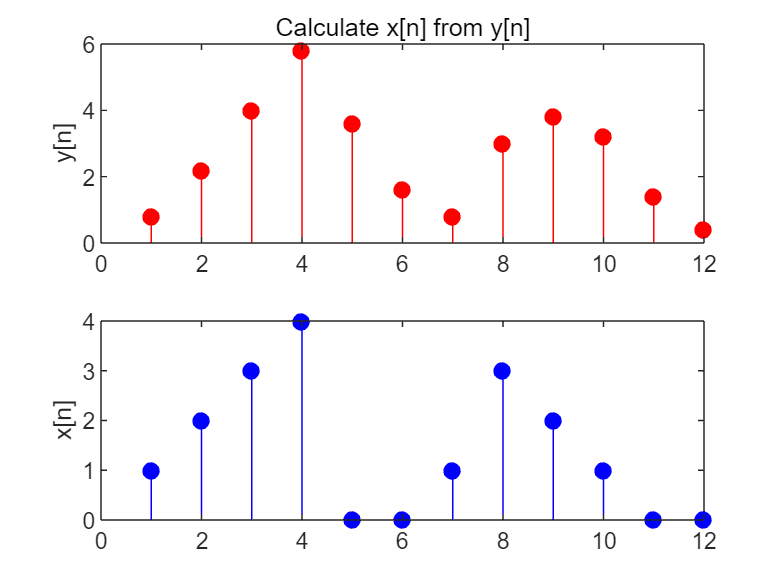

clc,clear,close all;
a=[0.8 0.6 0.4];
b=[1];
y=[0.8000 2.2000 4.0000 5.8000 3.6000 1.6000 0.8000 3.0000 3.8000 3.2000 1.4000 0.4000];
z=filter(b,a,y);
figure;
subplot(2,1,1),stem(y,'r','filled'),ylabel('y[n]');
title('Calculate x[n] from y[n]');
subplot(2,1,2),stem(z,'b','filled'),ylabel('x[n]');

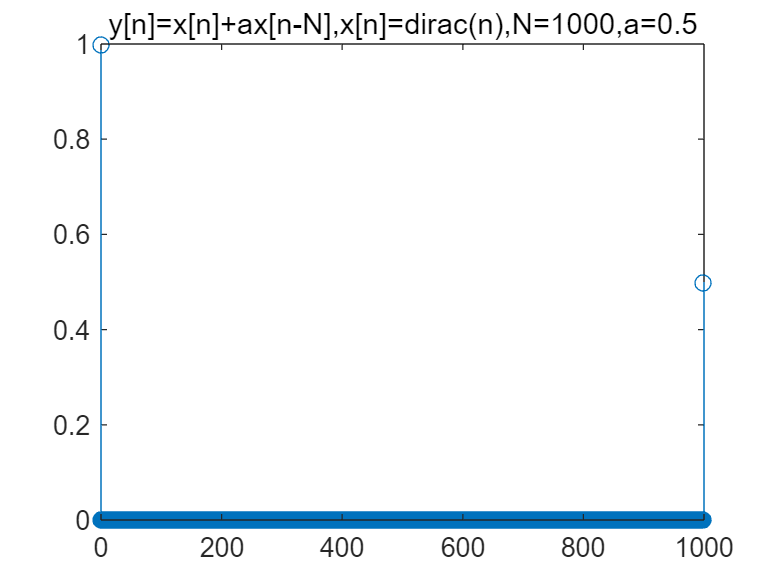

clc,clear,close all;
figure;
load lineup.mat;
sound(y,8192);
a=[1];
b=[1 zeros(1,999) 0.5];
n=0:1000;
x=(n==0);
y=filter(b,a,x);
stem(n,y),title('y[n]=x[n]+ax[n-N],x[n]=dirac(n),N=1000,a=0.5');

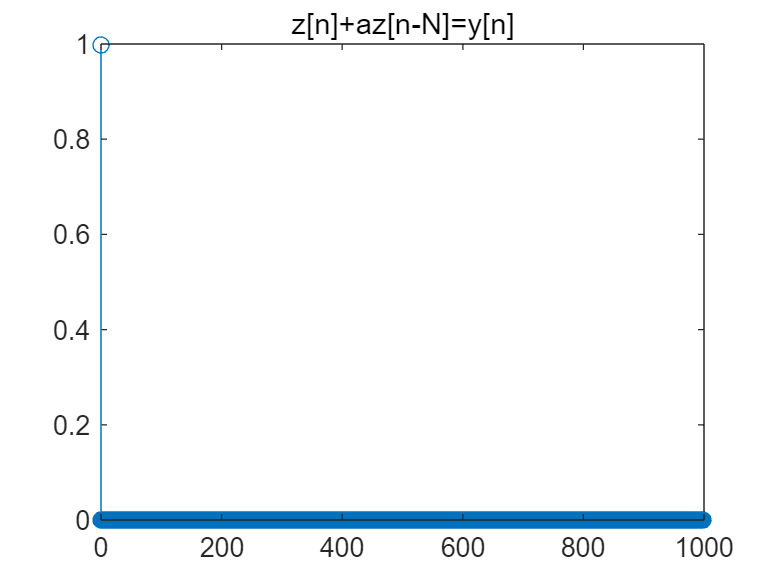

figure;
a=[1 zeros(1,999) 0.5];
b=[1];
z=filter(b,a,y);
stem(n,z),title('z[n]+az[n-N]=y[n]');

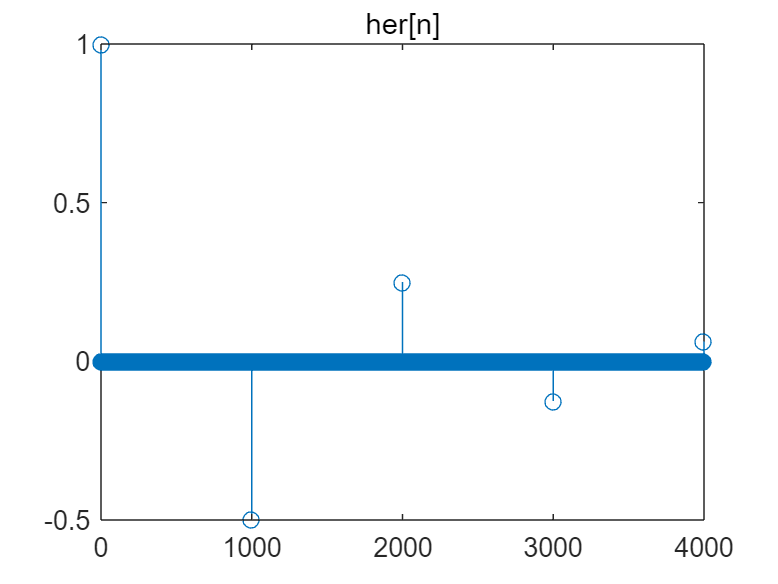

figure;
d=[1 zeros(1,4000)];
a=[1];
b=[1 zeros(1,999) 0.5];
n=0:4000;
her=filter(a,b,d);
stem(n,her),title('her[n]');

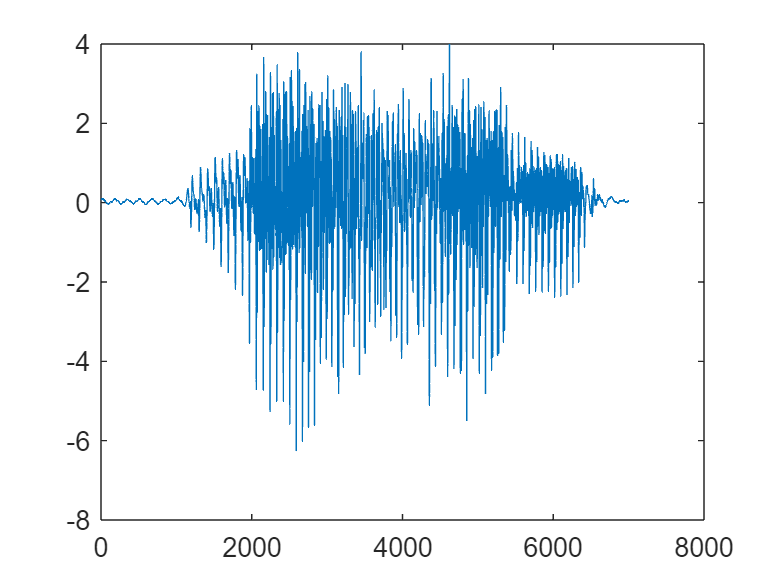

figure;
load lineup.mat;
z=filter(1,a,y);
nz=0:6999;
plot(nz,z);

sound(z,8192);

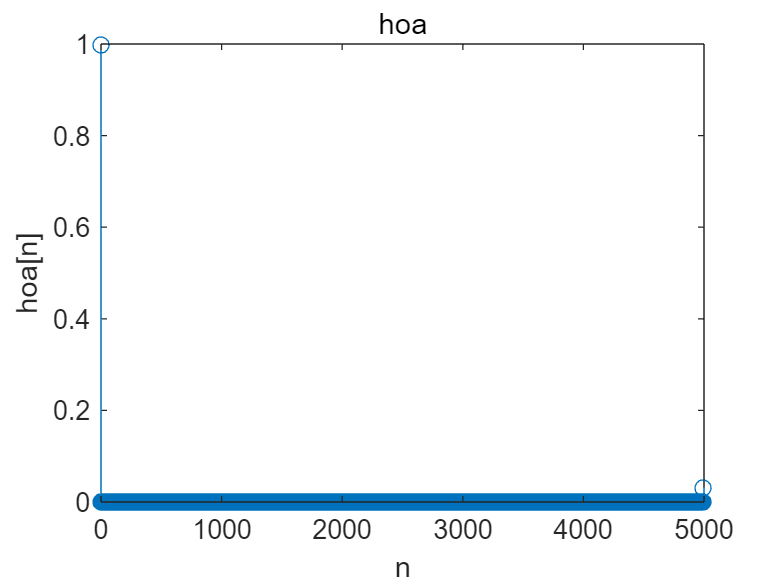

figure;
nhe=0:1000;
n=0:1000;
he=(n==0)+0.5*(n==1000);
nher=0:4000;
d=[1, zeros(1,4000)];
bx=1;
ay=[1,zeros(1,999),0.5];
her=filter(bx,ay,d);
hoa=conv(he,her);
nhoa=nhe(1)+nher(1):nhe(end)+nher(end);
figure;
stem(nhoa,hoa),title('hoa'),xlabel('n'),ylabel('hoa[n]');

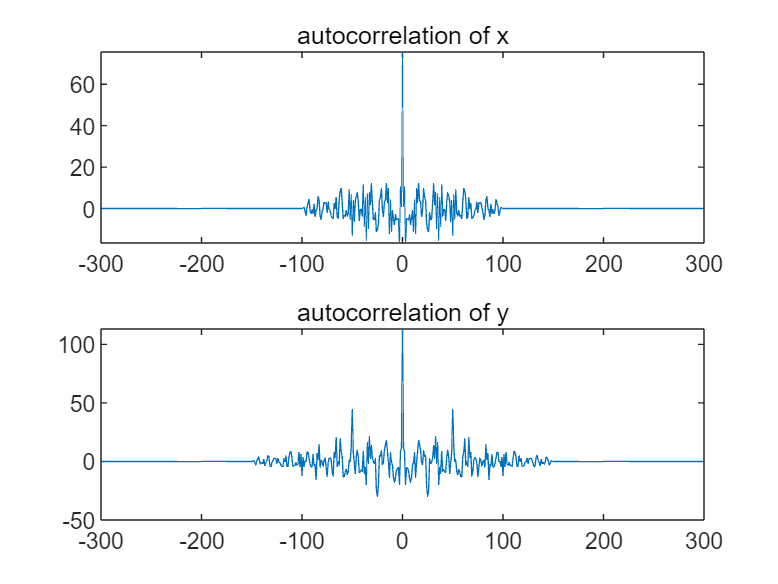

clc,clear,close all;
figure;
%加载x、y
NX = 100; X = randn(1,NX);
nX = 300; x = [X,zeros(1,200)];
N =50; alpha = 0.9;
y = filter([1,zeros(1,N-1),alpha],1,x);
%计算自相关
Rxx = conv(x,fliplr(x));
Ryy = conv(y,fliplr(y));
subplot(2,1,1), plot([-nX+1:nX-1],Rxx);
title('autocorrelation of x');
subplot(2,1,2), plot([-nX+1:nX-1],Ryy);
title('autocorrelation of y');

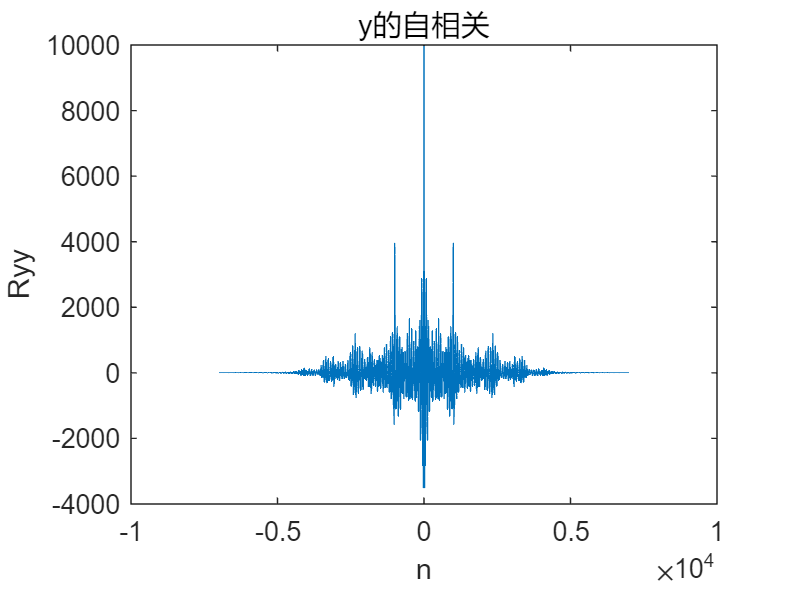

clc,clear,close all;
%y
figure;
%y的自相关
load lineup.mat;
Ryy=conv(y,flipud(y));
nY=7000;
plot([-nY+1:nY-1],Ryy),title('y的自相关'),xlabel('n'),ylabel('Ryy');

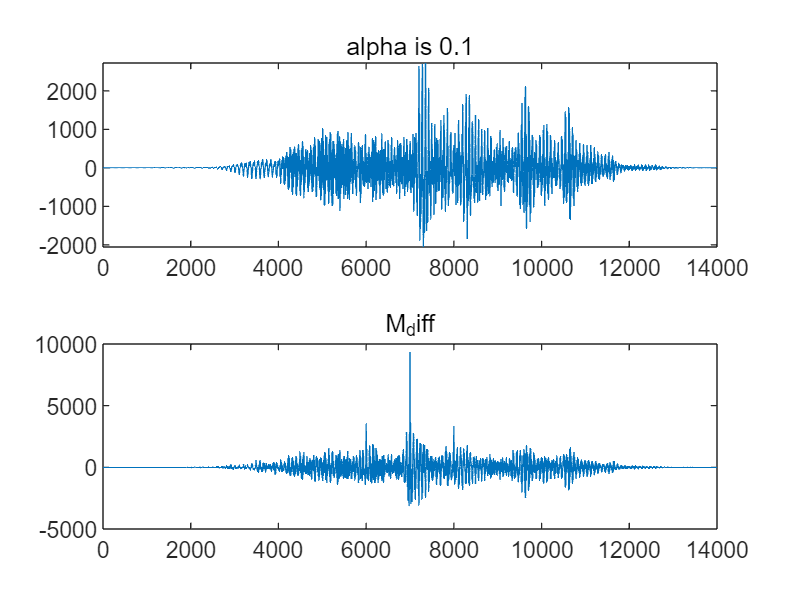

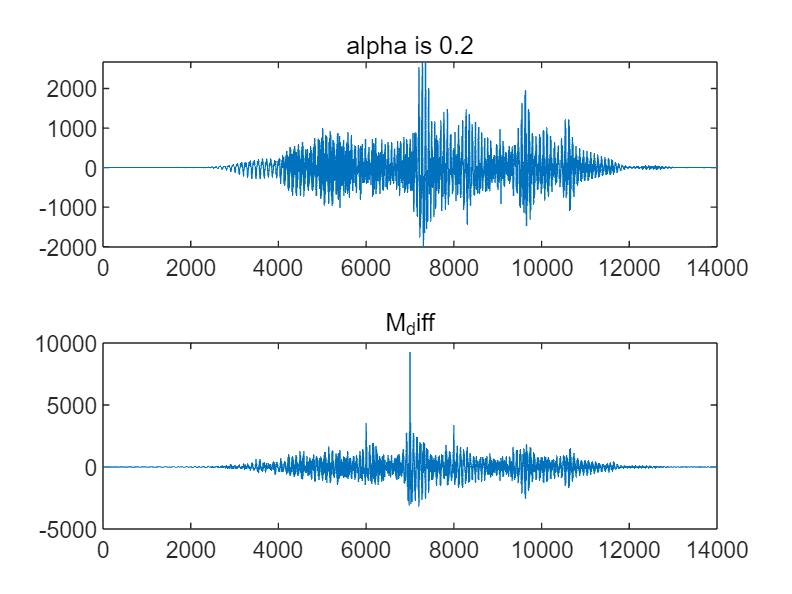

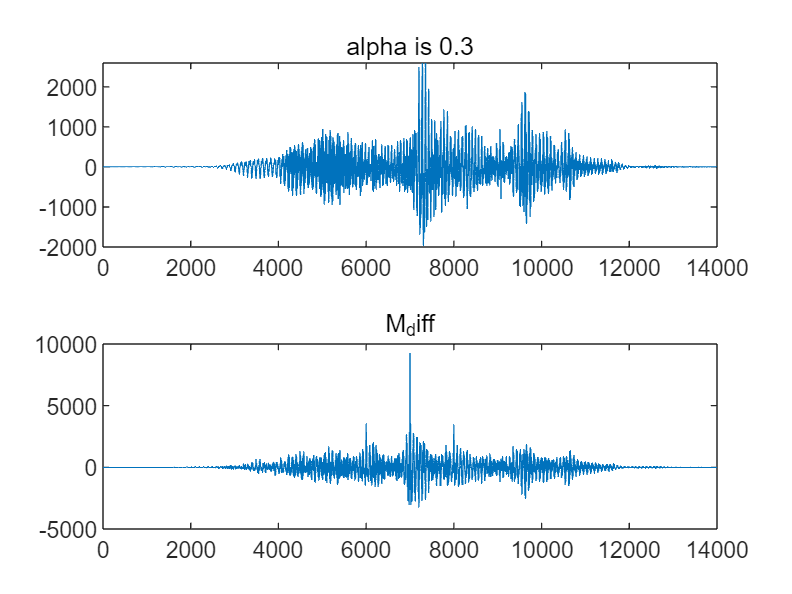

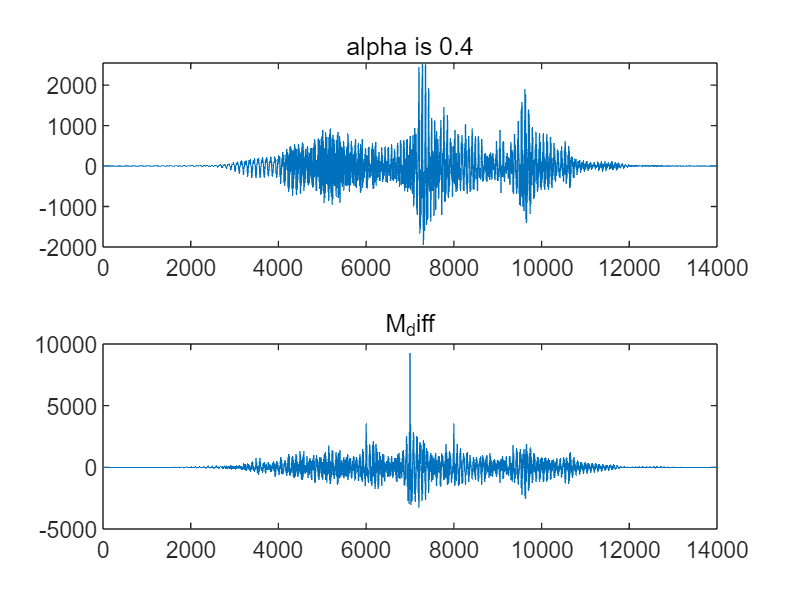

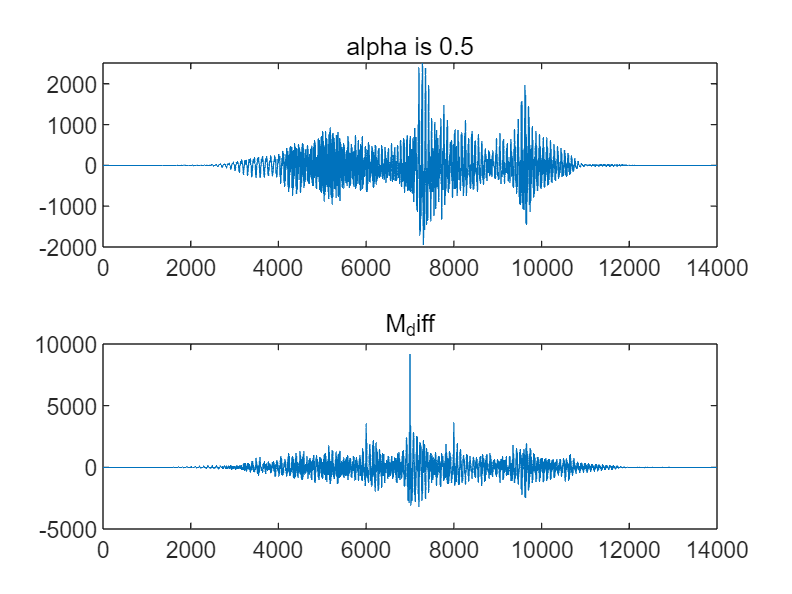

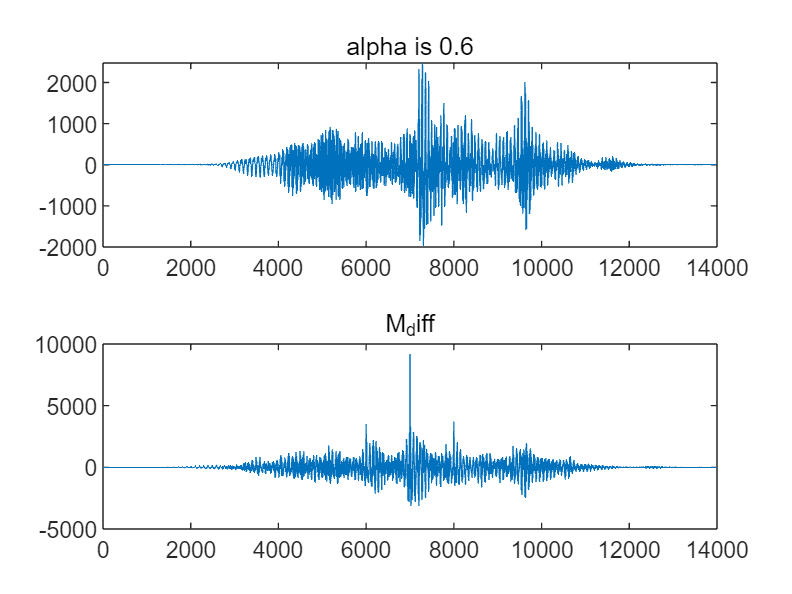

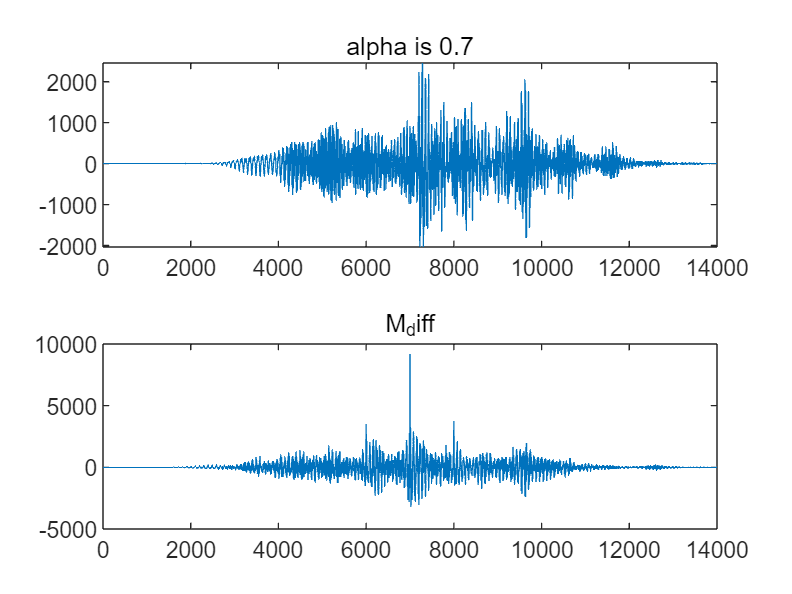

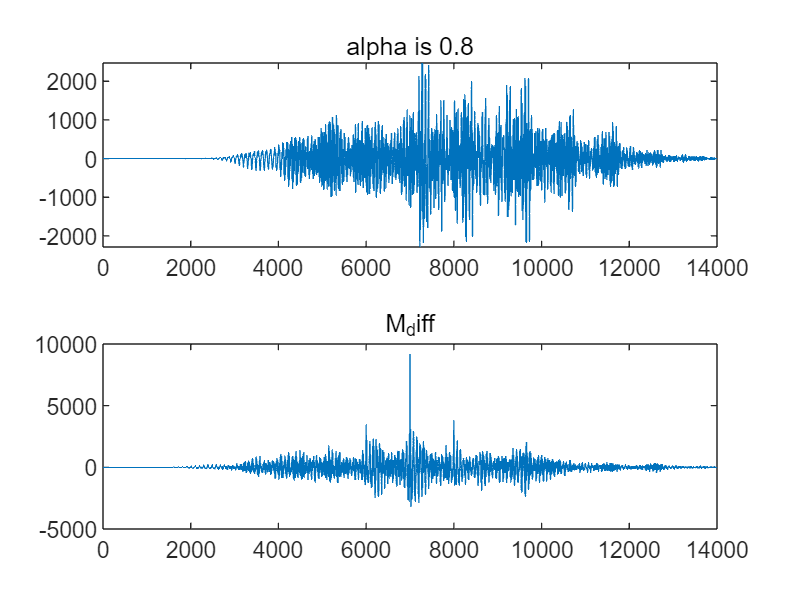

%观察图像，得N=1000
N=1000;
figure;
NX=7000;
%尝试alpha，计算x的自相关
for i=1:1:9
    alpha=i*0.1;
    x_re=filter(1,[1,zeros(1,N-1),alpha],y);
    Rxx_re=conv(x_re,fliplr(x_re))';
    M_diff=Ryy'-(1+alpha*alpha)*Rxx_re-alpha*[zeros(1,N) Rxx_re(1:2*NX-1-N)]-alpha*[Rxx_re(N+1:2*NX-1) zeros(1,N)];
    delta2(i)=std(M_diff.*M_diff);
    figure;
    subplot(2,1,1),plot(Rxx_re),title(['alpha is ',num2str(alpha)]);
    subplot(2,1,2),plot(M_diff),title('M_diff');
end

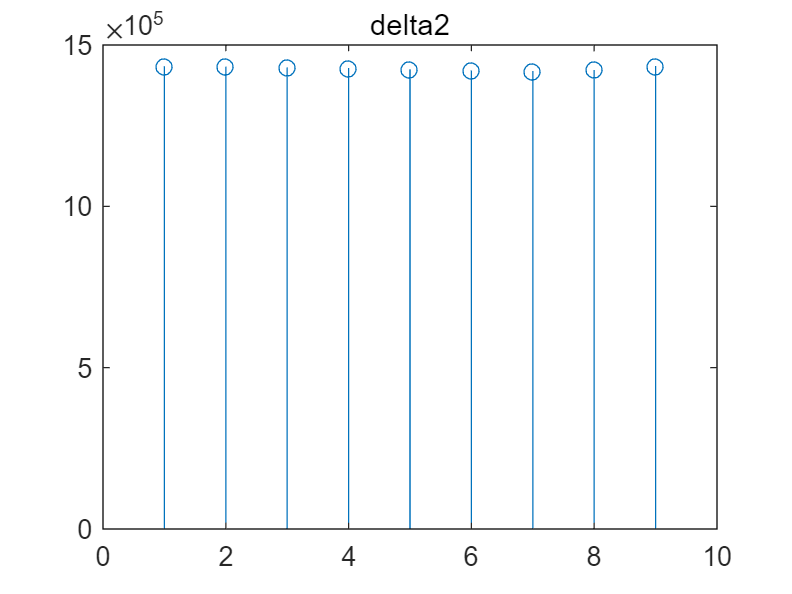

figure;
stem(delta2),title('delta2');

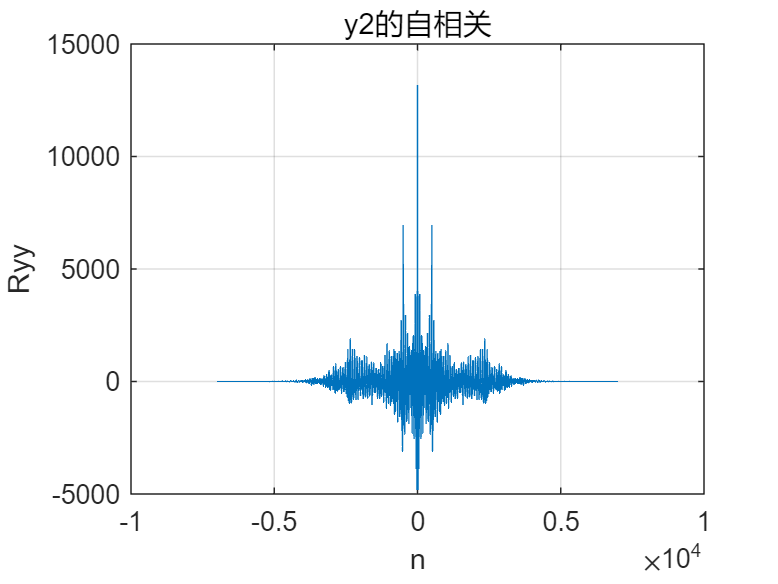

clc,clear,close all;
%y2
figure;
%y的自相关
load lineup.mat;
Ryy=conv(y2,flipud(y2));
nY=7000;
plot([-nY+1:nY-1],Ryy),title('y2的自相关'),xlabel('n'),ylabel('Ryy');

%观察图像，得N=501
N=501;
figure;
NX=7000;

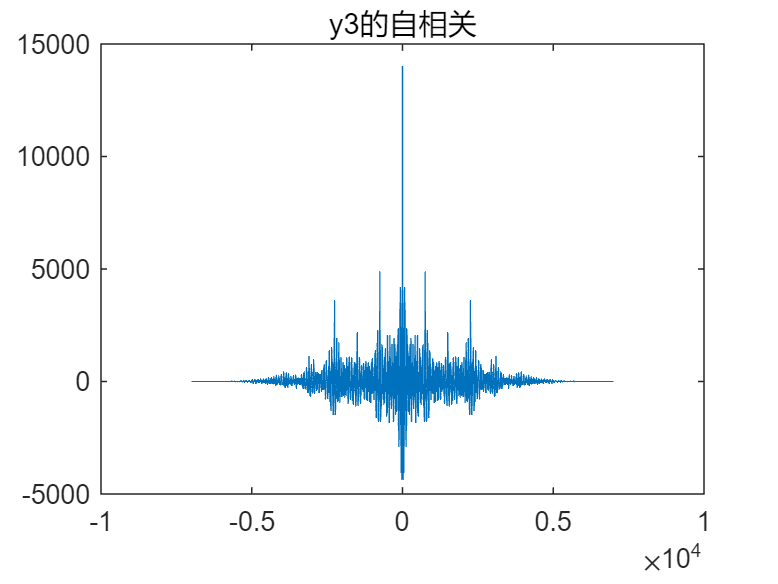

clc,clear,close all;
%y3
figure;
%y的自相关
load lineup.mat;
Ryy=conv(y3,flipud(y3));
nY=7000;
plot([-nY+1:nY-1],Ryy),title('y3的自相关'),xlabel('n'),ylabel('Ryy');

%观察图像，得N=751
N=751;
figure;
NX=7000;